srcDir = "..\srcImages\";

barbara = readraw(srcDir + "barbara.raw");

    "→Retrieving Image "    "..\srcImages\barbara.raw"    " ..."



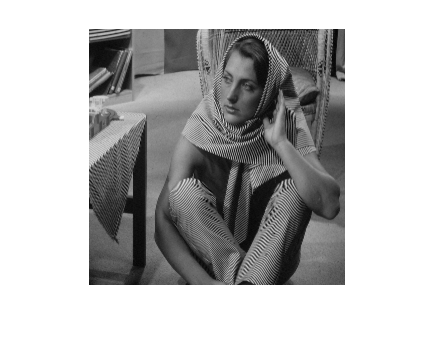

imshow(barbara);

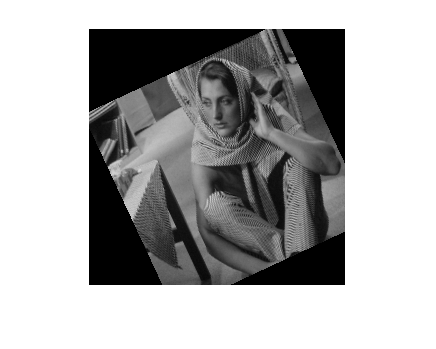


affectedBarbara = applyGeometryEffect(barbara, 3, 5, 2, 5);
imshow(affectedBarbara);

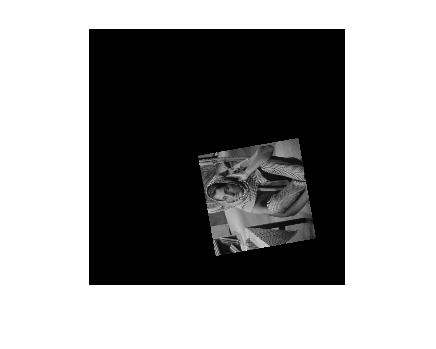


affectedBarbara = applyGeometryEffect(barbara, 3, 5, 2, 20);
imshow(affectedBarbara);

baboon = readraw(srcDir + "baboon.raw");

    "→Retrieving Image "    "..\srcImages\baboon.raw"    " ..."



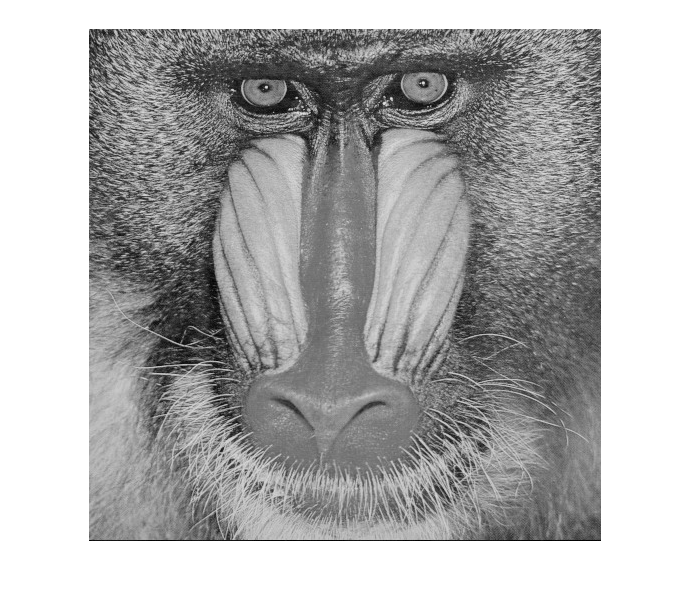

imshow(baboon);

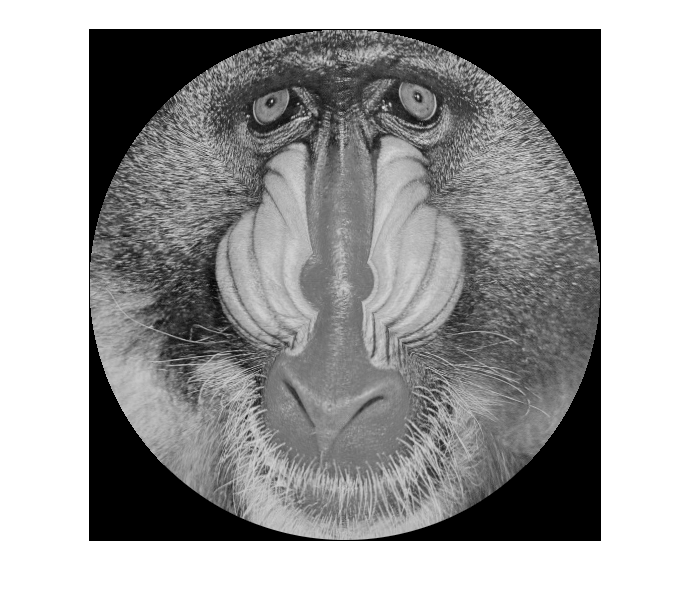


diskBaboon = toDisk(baboon);
imshow(diskBaboon);

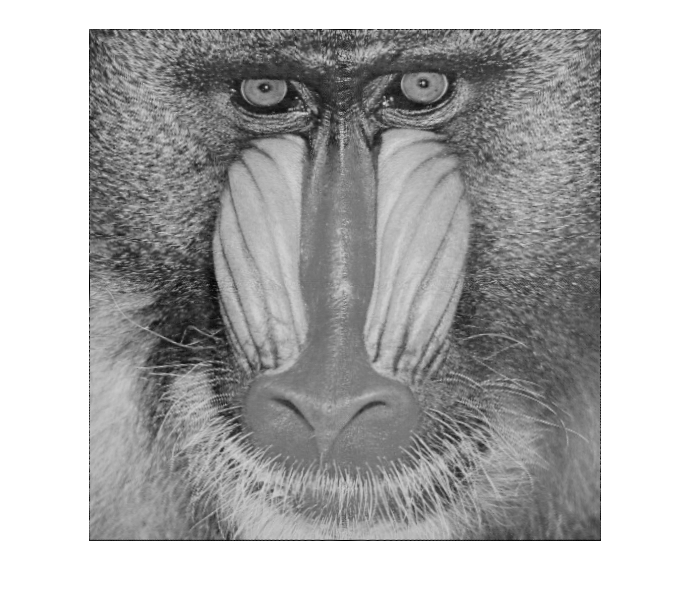


resquaredBaboon = fromDisk(diskBaboon);
imshow(resquaredBaboon);


%diskBaboon = warp(barbara, inverseDisk(128.5));
%imshow(diskBaboon);

%resquaredBaboon = fromDisk(baboon);
%imshow(resquaredBaboon);
%imshow(toDisk(resquaredBaboon));

txClasses = zeros(64, 64, 15);
for i = 1:15
    txClasses(:, :, i) = readraw(srcDir + "sample" + string(i) + ".raw");
end

    "→Retrieving Image "    "..\srcImages\sample1.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample2.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample3.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample4.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample5.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample6.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample7.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample8.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample9.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample10.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample11.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample12.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample13.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample14.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample15.raw"    " ..."




classes = classifyLawsSmallTextures(txClasses, 5);

mosaic1 = readraw(srcDir + "comb1.raw");
imshow(mosaic1);
clustered = clusterTextures(mosaic1, [0, 63, 127, 191, 255]);
imshow(clustered);
segmented = segmentClusters(clustered, [0, 63, 127, 191, 255]);
imshow(segmented);

mosaic2 = readraw(srcDir + "comb2.raw");

    "→Retrieving Image "    "..\srcImages\comb2.raw"    " ..."



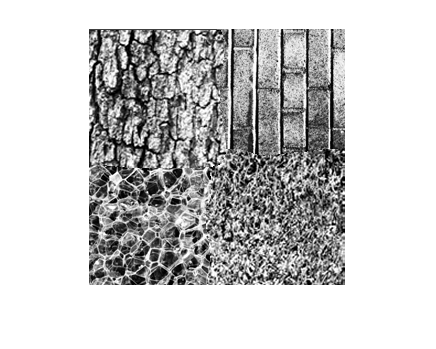

imshow(mosaic2);

clustered = clusterTextures(mosaic2, [0, 85, 170, 255]);

cluster error is 1818854.0215
cluster error is 1818853.9095
cluster error is 1818853.9095
cluster error is 1818853.9058
cluster error is 1818853.9095


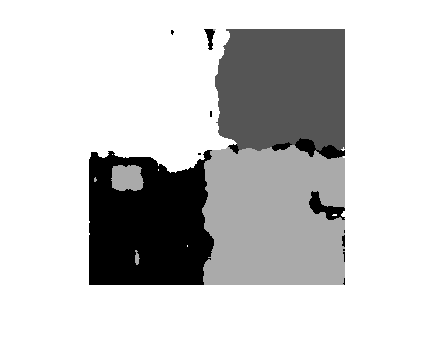

imshow(clustered);

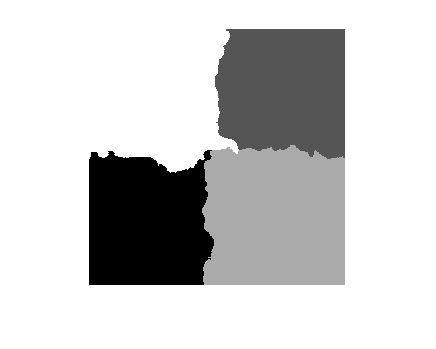

segmented = segmentClusters(clustered, [0, 85, 170, 255]);
imshow(segmented);

colors = [0, 85, 170, 255];
connectedParts = connectedComponents(segmented2);
frequencyList = frequencies(connectedParts);
keptComponents = largestComponents(segmented2, connectedParts, [0, 85, 170, 255], frequencyList);
segmented = mergeComponents(connectedParts, frequencyList, keptComponents);
[rows, cols] = size(connectedParts);
for row = 1:rows
    for col = 1:cols
        for i = 1:4
            if segmented(row, col) == keptComponents(i)
                segmented(row, col) = colors(i);
            end
        end
    end
end
imshow(uint8(segmented));

training = toGrayScale(readraw_color(srcDir + "training.raw"));

    "→Retrieving Image "    "..\srcImages\training.raw"    " ..."



test1 = toGrayScale(readraw_color(srcDir + "test1.raw"));

    "→Retrieving Image "    "..\srcImages\test1.raw"    " ..."



test2 = readraw(srcDir + "test2.raw");

    "→Retrieving Image "    "..\srcImages\test2.raw"    " ..."



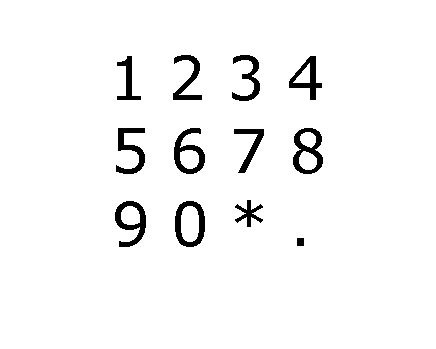

imshow(training);

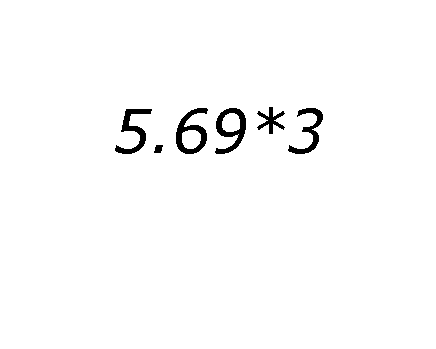

imshow(test1);

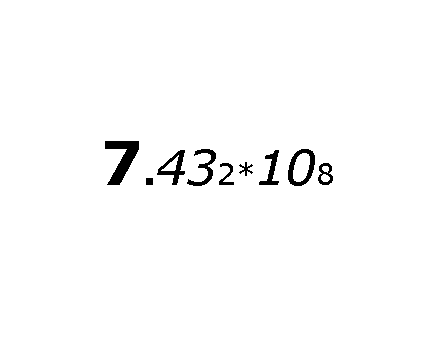

imshow(test2);

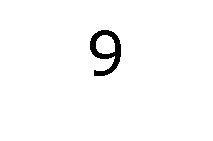

56.4118 44.0078


ans =   OcrFeatures with properties:

                area: 608
           perimeter: 280
            eulerNum: 0
         circularity: 0.0975
    spatialMomentRow: -414.8615
    spatialMomentCol: -470.7506
           symmetryX: 0.5691
           symmetryY: 0.8553
         aspectRatio: 1.4545
    convexDeficiency: 1.1102


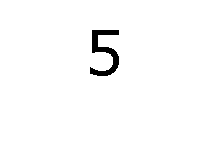

52.9569 36.7882


ans =   OcrFeatures with properties:

                area: 564
           perimeter: 244
            eulerNum: 1
         circularity: 0.1190
    spatialMomentRow: -340.9098
    spatialMomentCol: -366.6956
           symmetryX: 0.9043
           symmetryY: 1.1277
         aspectRatio: 1.5484
    convexDeficiency: 1.6383


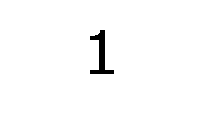

38.7843 19.4118


ans =   OcrFeatures with properties:

                area: 374
           perimeter: 154
            eulerNum: 1
         circularity: 0.1982
    spatialMomentRow: -100.3333
    spatialMomentCol: -88.8462
           symmetryX: 0.2353
           symmetryY: 0.6203
         aspectRatio: 1.7692
    convexDeficiency: 2.1979


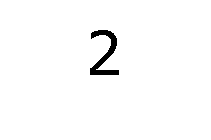

50.5294 32.7412


ans =   OcrFeatures with properties:

                area: 492
           perimeter: 238
            eulerNum: 1
         circularity: 0.1091
    spatialMomentRow: -254.7972
    spatialMomentCol: -250.3116
           symmetryX: 0.9390
           symmetryY: 1.0203
         aspectRatio: 1.5161
    convexDeficiency: 1.9614


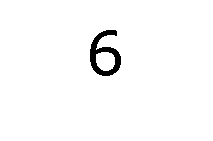

62.9 39.3863


ans =   OcrFeatures with properties:

                area: 609
           perimeter: 280
            eulerNum: 0
         circularity: 0.0976
    spatialMomentRow: -463.8875
    spatialMomentCol: -422.5073
           symmetryX: 0.5714
           symmetryY: 0.8506
         aspectRatio: 1.4545
    convexDeficiency: 1.1067


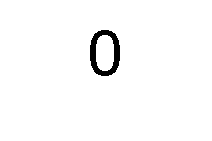

59.002 40.0333


ans =   OcrFeatures with properties:

                area: 601
           perimeter: 260
            eulerNum: 0
         circularity: 0.1117
    spatialMomentRow: -425.3058
    spatialMomentCol: -432.8604
           symmetryX: 0.0033
           symmetryY: 0.0033
         aspectRatio: 1.5000
    convexDeficiency: 0.6173


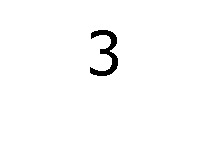

47.7353 35.6294


ans =   OcrFeatures with properties:

                area: 487
           perimeter: 242
            eulerNum: 1
         circularity: 0.1045
    spatialMomentRow: -230.7206
    spatialMomentCol: -275.5341
           symmetryX: 0.9979
           symmetryY: 0.4230
         aspectRatio: 1.6000
    convexDeficiency: 1.9569


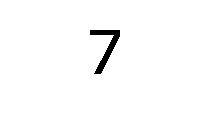

30.0235 29.6078


ans =   OcrFeatures with properties:

                area: 410
           perimeter: 188
            eulerNum: 1
         circularity: 0.1458
    spatialMomentRow: -101.1662
    spatialMomentCol: -143.4130
           symmetryX: 1.0634
           symmetryY: 1.4537
         aspectRatio: 1.4375
    convexDeficiency: 2.5902


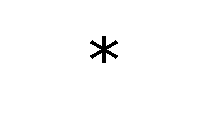

17.6275 18.1961


ans =   OcrFeatures with properties:

                area: 290
           perimeter: 202
            eulerNum: 1
         circularity: 0.0893
    spatialMomentRow: -21.2745
    spatialMomentCol: -21.2288
           symmetryX: 0
           symmetryY: 0
         aspectRatio: 1.0345
    convexDeficiency: 2


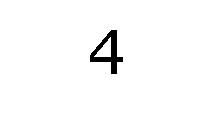

49.6608 42.0882


ans =   OcrFeatures with properties:

                area: 521
           perimeter: 228
            eulerNum: 0
         circularity: 0.1259
    spatialMomentRow: -287.1689
    spatialMomentCol: -319.8706
           symmetryX: 1.0211
           symmetryY: 0.7255
         aspectRatio: 1.3143
    convexDeficiency: 1.7486


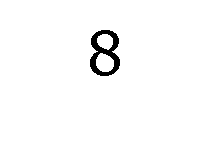

63.0706 42.7882


ans =   OcrFeatures with properties:

                area: 646
           perimeter: 318
            eulerNum: -1
         circularity: 0.0803
    spatialMomentRow: -513.7625
    spatialMomentCol: -522.8188
           symmetryX: 0.1610
           symmetryY: 0.4272
         aspectRatio: 1.5000
    convexDeficiency: 0.6656


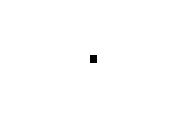

6 5.5


ans =   OcrFeatures with properties:

                area: 56
           perimeter: 30
            eulerNum: 1
         circularity: 0.7819
    spatialMomentRow: 0
    spatialMomentCol: 0
           symmetryX: 0
           symmetryY: 0
         aspectRatio: 1.1111
    convexDeficiency: 0.6071



hullBounds = convexHullsFor(training);
[hulls, ~] = size(hullBounds);
for i = 1:hulls
    figure;
    convexHull = binaryImgForBounds(training, hullBounds(i, :));
    imshow(fromBinary(convexHull));
    ocrFeaturesForHull(convexHull)
end

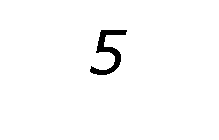

50.3529 43.6118


ans =   OcrFeatures with properties:

                area: 544
           perimeter: 246
            eulerNum: 1
         circularity: 0.1130
    spatialMomentRow: -309.6170
    spatialMomentCol: -323.1744
           symmetryX: 1.2610
           symmetryY: 1.4301
         aspectRatio: 1.2051
    convexDeficiency: 2.3695


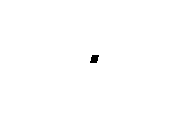

6 6.5


ans =   OcrFeatures with properties:

                area: 56
           perimeter: 34
            eulerNum: 1
         circularity: 0.6088
    spatialMomentRow: 0
    spatialMomentCol: 0
           symmetryX: 0.2857
           symmetryY: 0.2857
         aspectRatio: 1.1000
    convexDeficiency: 0.9643


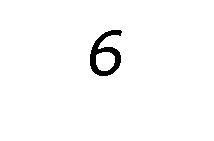

63.5569 41.6275


ans =   OcrFeatures with properties:

                area: 616
           perimeter: 284
            eulerNum: 0
         circularity: 0.0960
    spatialMomentRow: -478.0006
    spatialMomentCol: -441.9856
           symmetryX: 0.7922
           symmetryY: 1.3442
         aspectRatio: 1.4118
    convexDeficiency: 1.1591


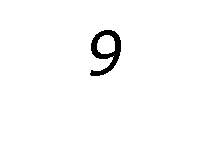

55.5922 42.9216


ans =   OcrFeatures with properties:

                area: 600
           perimeter: 282
            eulerNum: 0
         circularity: 0.0948
    spatialMomentRow: -399.5686
    spatialMomentCol: -448.7255
           symmetryX: 0.7867
           symmetryY: 1.3267
         aspectRatio: 1.4545
    convexDeficiency: 1.1600


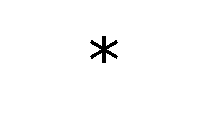

17.4314 18.051


ans =   OcrFeatures with properties:

                area: 288
           perimeter: 202
            eulerNum: 1
         circularity: 0.0887
    spatialMomentRow: -19.8357
    spatialMomentCol: -19.8561
           symmetryX: 0.0139
           symmetryY: 0.0278
         aspectRatio: 1.0345
    convexDeficiency: 2.0208


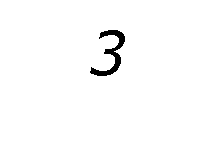

48.3216 44.8235


ans =   OcrFeatures with properties:

                area: 488
           perimeter: 254
            eulerNum: 1
         circularity: 0.0951
    spatialMomentRow: -234.5609
    spatialMomentCol: -282.2671
           symmetryX: 1.4631
           symmetryY: 1.1393
         aspectRatio: 1.2973
    convexDeficiency: 2.6393



%hullBounds = convexHullsFor(test1);
%[hulls, ~] = size(hullBounds);
%for i = 1:hulls
%    figure;
%    convexHull = binaryImgForBounds(test1, hullBounds(i, :));
%    imshow(fromBinary(convexHull));
%    ocrFeaturesForHull(convexHull)
%end

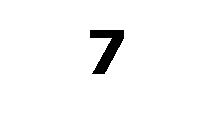

55.5235 55.4373


ans =   OcrFeatures with properties:

                area: 717
           perimeter: 196
            eulerNum: 1
         circularity: 0.2345
    spatialMomentRow: -557.6494
    spatialMomentCol: -711.4448
           symmetryX: 0.8508
           symmetryY: 1.0516
         aspectRatio: 1.2778
    convexDeficiency: 1.3096


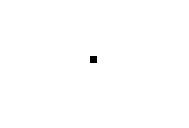

5.5 5.5


ans =   OcrFeatures with properties:

                area: 49
           perimeter: 28
            eulerNum: 1
         circularity: 0.7854
    spatialMomentRow: 0
    spatialMomentCol: 0
           symmetryX: 0
           symmetryY: 0
         aspectRatio: 1
    convexDeficiency: 0.6531


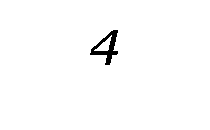

26.6922 26.1627


ans =   OcrFeatures with properties:

                area: 349
           perimeter: 208
            eulerNum: 0
         circularity: 0.1014
    spatialMomentRow: -67.8125
    spatialMomentCol: -81.9766
           symmetryX: 1.1289
           symmetryY: 1.0831
         aspectRatio: 1.2333
    convexDeficiency: 1.8481


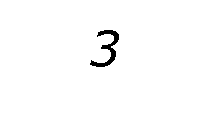

26.5294 25.6235


ans =   OcrFeatures with properties:

                area: 330
           perimeter: 208
            eulerNum: 1
         circularity: 0.0959
    spatialMomentRow: -51.0181
    spatialMomentCol: -61.9924
           symmetryX: 1.4424
           symmetryY: 1.1636
         aspectRatio: 1.2581
    convexDeficiency: 2.6636


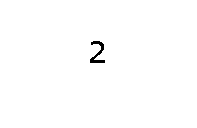

14.0075 9.791


ans =   OcrFeatures with properties:

                area: 134
           perimeter: 116
            eulerNum: 1
         circularity: 0.1251
    spatialMomentRow: -4.0116e-14
    spatialMomentCol: -8.9863e-15
           symmetryX: 0.8209
           symmetryY: 0.9254
         aspectRatio: 1.4118
    convexDeficiency: 2.0448


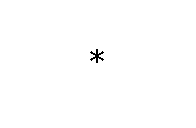

9 9


ans =   OcrFeatures with properties:

                area: 76
           perimeter: 100
            eulerNum: 1
         circularity: 0.0955
    spatialMomentRow: 0
    spatialMomentCol: 0
           symmetryX: 0
           symmetryY: 0
         aspectRatio: 1
    convexDeficiency: 2.3684


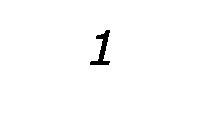

22.5373 15.0039


ans =   OcrFeatures with properties:

                area: 266
           perimeter: 138
            eulerNum: 1
         circularity: 0.1755
    spatialMomentRow: -6.7003
    spatialMomentCol: -7.5020
           symmetryX: 1.0827
           symmetryY: 1
         aspectRatio: 1.6818
    convexDeficiency: 2.0602


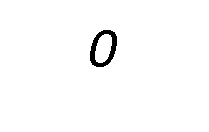

32.8 24.8


ans =   OcrFeatures with properties:

                area: 408
           perimeter: 220
            eulerNum: 0
         circularity: 0.1059
    spatialMomentRow: -128.6769
    spatialMomentCol: -130.8414
           symmetryX: 1.1373
           symmetryY: 1.1373
         aspectRatio: 1.3448
    convexDeficiency: 0.8578


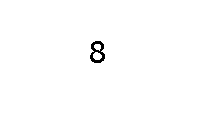

13.259 9.5482


ans =   OcrFeatures with properties:

                area: 166
           perimeter: 148
            eulerNum: -1
         circularity: 0.0952
    spatialMomentRow: -2.5461e-14
    spatialMomentCol: -5.8515e-15
           symmetryX: 0.1205
           symmetryY: 0.5060
         aspectRatio: 1.4118
    convexDeficiency: 0.8976



%hullBounds = convexHullsFor(test2);
%[hulls, ~] = size(hullBounds);
%for i = 1:hulls
%    figure;
%    convexHull = binaryImgForBounds(test2, hullBounds(i, :));
%    imshow(fromBinary(convexHull));
%    ocrFeaturesForHull(convexHull)
%end

training = toGrayScale(readraw_color(srcDir + "training.raw"));

    "→Retrieving Image "    "..\srcImages\training.raw"    " ..."



test1 = toGrayScale(readraw_color(srcDir + "test1.raw"));

    "→Retrieving Image "    "..\srcImages\test1.raw"    " ..."



test2 = readraw(srcDir + "test2.raw");

    "→Retrieving Image "    "..\srcImages\test2.raw"    " ..."



imshow(training);

imshow(test1);


imshow(test1);

five


dot


six


nine


star


three


charClasses = buildOcrClasses(training);
classified = ocrSegmentAndClassify(test1, charClasses);
[~, toShow] = size(classified);
for i = 1:toShow
    figure;
    imshow(fromBinary(classified(i).convexHull));
    disp(classified(i).textName);
end


imshow(test2);

seven


dot


four


three


two


star


one


zero


eight


classified = ocrSegmentAndClassify(test2, charClasses);
[~, toShow] = size(classified);
for i = 1:toShow
    figure;
    imshow(fromBinary(classified(i).convexHull));
    disp(classified(i).textName);
end